Author: Warren Chan

Date: 2022-03-18

This livescript is to be used to develop the script that will allow to generate the graphs. This just allows for easier debugging and section by section visualization of results. You can ignore the warning message below, it only pertains to the specific formatting fo the headers of a table being used

Check out the main overlayed result shown in the last graph.

clear;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%CHANGE THESE TWO TO CHANGE THE DATA
load_cell_number = 3;
test_number = 1; % note that this is not the test TYPE (stepped loading, etc)

load_cell_number = 1;
test_number = 1;

MCU_T1_LC1_data = readtable("MCU\Instron_stepT"+test_number+"_lc"+load_cell_number+".csv");
INSTRON_T1_LC1_data = readtable("Instron\PhysViz_Step_t"+test_number+"_lc"+load_cell_number+"\Test1\Test1.Stop.csv");

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% MCU Data
% loading data into vectors
MCU_load = MCU_T1_LC1_data{:,1};
MCU_time = MCU_T1_LC1_data{:,2};

% formatting the MCU_time to get only seconds
for item = 1:length(MCU_time)

    timestring = string(MCU_time(item));            %get the datetime string
    timestring = erase(timestring, "2022-03-11");   %remove the unwanted year-month-day information
    timestring = strtrim(timestring);               %remove leading whitespace
    substrings = split(timestring,":");             %splitting into the hours:minutes:seconds
    subdoubles = str2double(substrings);            %convert to doubles

    current_hour = subdoubles(1);
    current_minute = subdoubles(2);
    current_seconds = subdoubles(3);

    if (item == 1)
        reference_seconds = current_hour*60*60 + current_minute*60 + current_seconds;
    end

    MCU_time_seconds(item) = current_hour*60*60 + current_minute*60 + current_seconds - reference_seconds;    
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% note that for the imported Instron data:
% column 9: load information
% column 1: time information
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Instron load data
Instron_load = INSTRON_T1_LC1_data{:,9};
Instron_load_scaled = Instron_load.*(1000/1.3831); % this is used for visualization purposes later on
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Instron time data
Instron_time = INSTRON_T1_LC1_data{:,1};


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Using Correlation to find the best index shift
% this implements shifting of the Instron data

%first process the data from the MCU
%we need to interpolate to match the frequency of the instron

%get the duration of the MCU
%get the duration of the Instron
%interpolate data of the MCu to match the time steps of the Instron

%these calculations assume a fixed sampling rate for both the MCU and
%instron. This is an approximation
total_duration_MCU = MCU_time_seconds(end); %end time in seconds
total_duration_Instron = Instron_time(end); %end time in seconds
%trying using interp1

%methodology:
% resample both the MCU and Instron data to be at same frequency

%creating a new time arrays
new_seconds_timestep = 0.0001;

MCU_new_time_array = [0:new_seconds_timestep:total_duration_MCU];
Instron_new_time_array = [0:new_seconds_timestep:total_duration_Instron];

MCU_interp1_load = interp1(MCU_time_seconds, MCU_load, MCU_new_time_array);

The graph below plots the raw readings obtained using prototype 2.

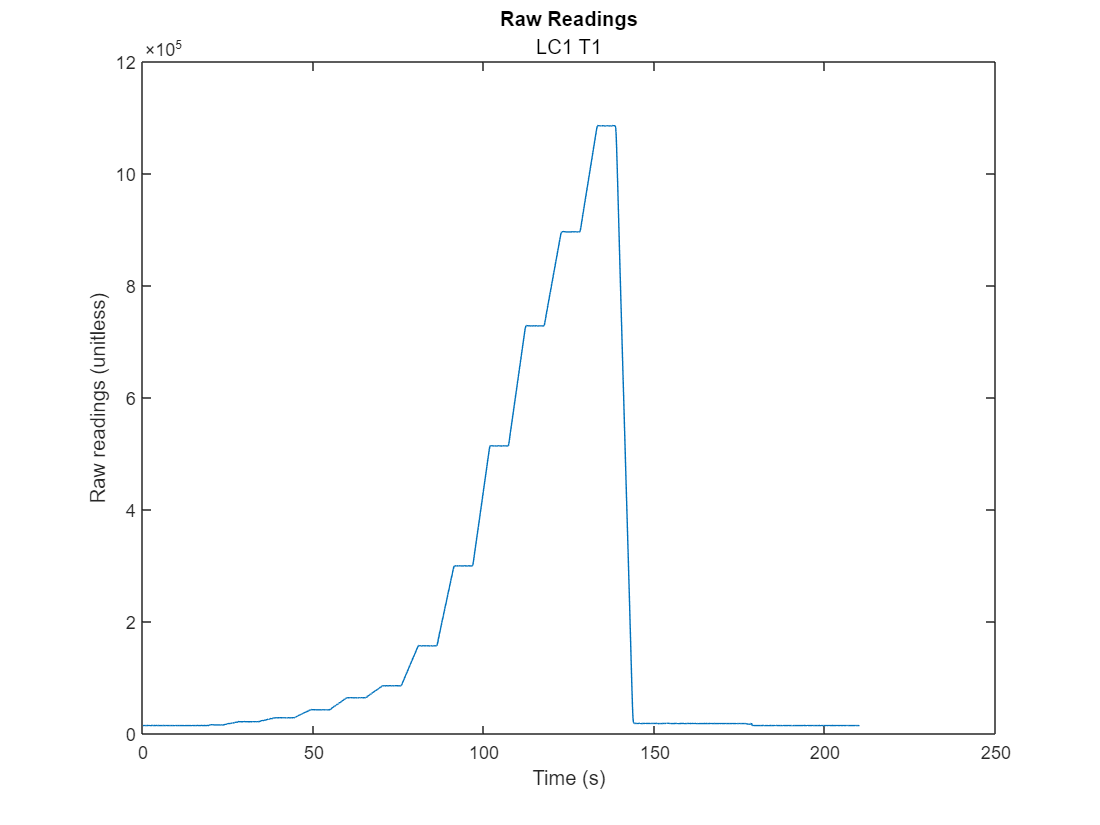

plot(MCU_new_time_array, MCU_interp1_load);
hold on
title("Raw Readings",{"LC"+load_cell_number + " T" + test_number});
xlabel("Time (s)");
ylabel("Raw readings (unitless)");
set(gcf,'position',[10,10,900,600]);
hold off

[Instron_unique_time, unique_locations] = unique(Instron_time);
Instron_unique_loads = zeros(length(unique_locations),1);
%use unique_locations to resample the actual data to only the ones
%corresponding to unique times
for item = 1:length(unique_locations)
    Instron_unique_loads(item) = Instron_load(unique_locations(item));
end

Instron_interp1_load = interp1(Instron_unique_time, Instron_unique_loads, Instron_new_time_array);


The graph below shows the data obtained from the load cell within the Instron setup. These are the values to be used in our calibration process as reference.

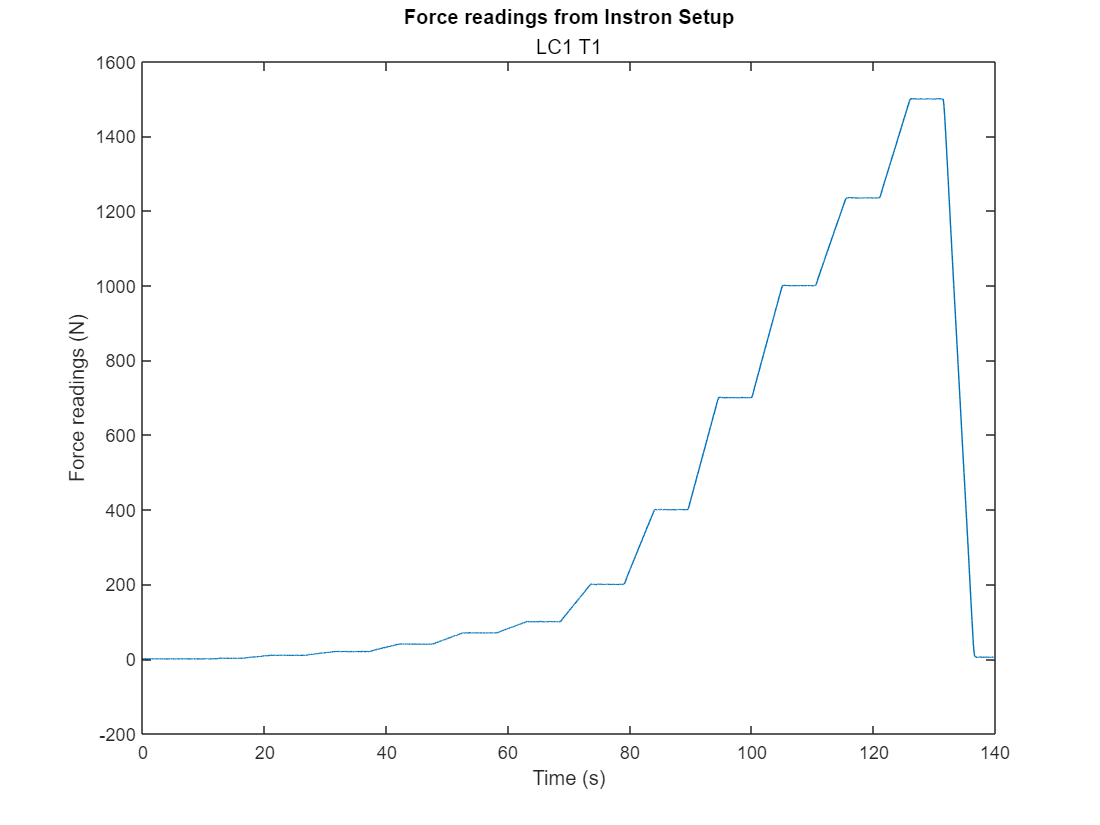

plot (Instron_new_time_array,Instron_interp1_load);
hold on
title("Force readings from Instron Setup",{"LC"+load_cell_number + " T" + test_number});
xlabel("Time (s)");
ylabel("Force readings (N)");
set(gcf,'position',[10,10,900,600]);
hold off

The graph below shows the two sets of data overlaid, with the Instron data scaled up for visualization purposes along with the raw readings obtained using our prototype.

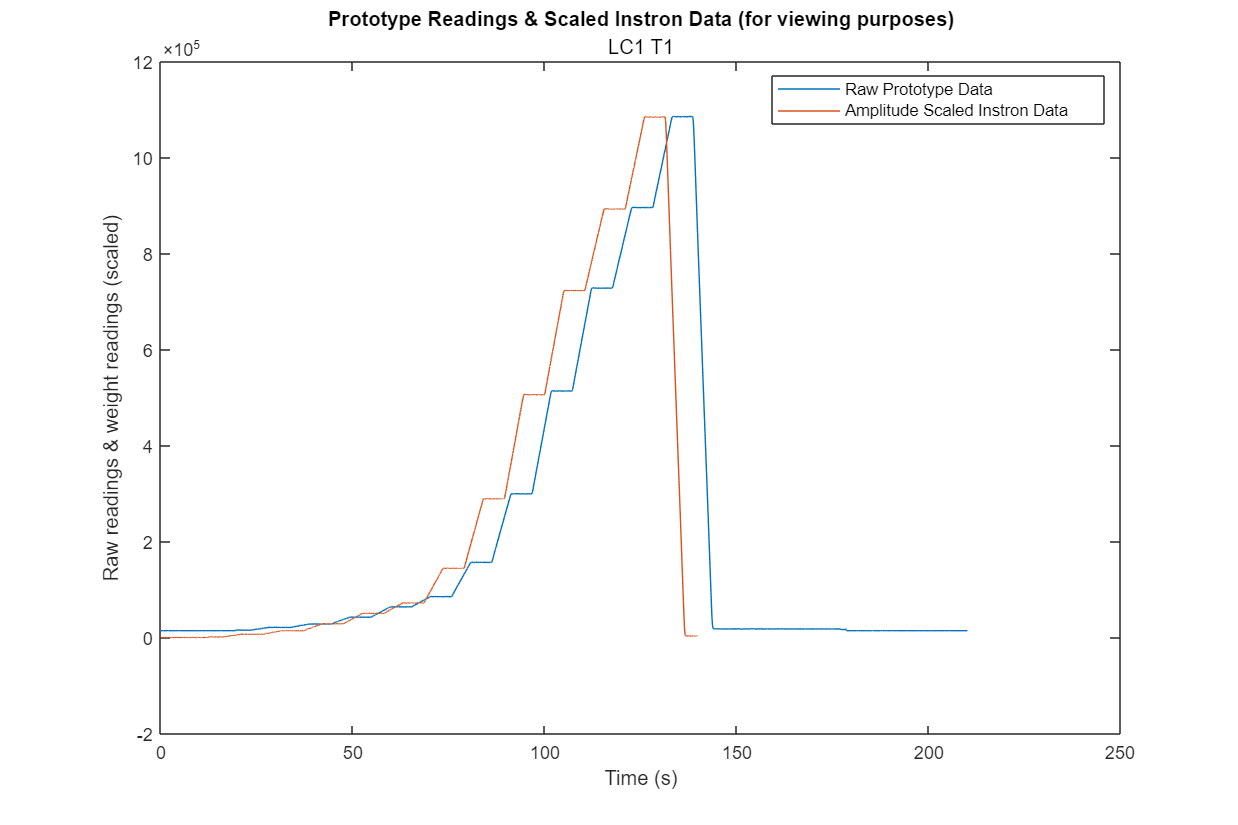

%note that the graph generated by the code below uses the raw data obtained
%from both setups, and does NOT use the interpolated datasets.
plot(MCU_time_seconds, MCU_load);
hold on
plot(Instron_time, Instron_load_scaled);
title("Prototype Readings & Scaled Instron Data (for viewing purposes)",{"LC"+load_cell_number + " T" + test_number});
xlabel("Time (s)"); %note that the time used for reference is the Instron timing;
ylabel("Raw readings & weight readings (scaled)");
legend("Raw Prototype Data","Amplitude Scaled Instron Data");
% set(gcf,'position',[10,10,900,600]);
hold off



[new_cross_correl, lags2] = xcorr(Instron_interp1_load,MCU_interp1_load);

maxcorrelindex2 = find(new_cross_correl == max(new_cross_correl));
maxlags2 = lags2(maxcorrelindex2);
correspondingtimelag = maxlags2 * new_seconds_timestep;

The graph below shows the cross correlation of the Instron data with the raw readings obtained by our prototype. The vertical line indicates the determined location where the cross correlation is maximized. A reference slide on cross correlation is included for readers of this livescript:

                       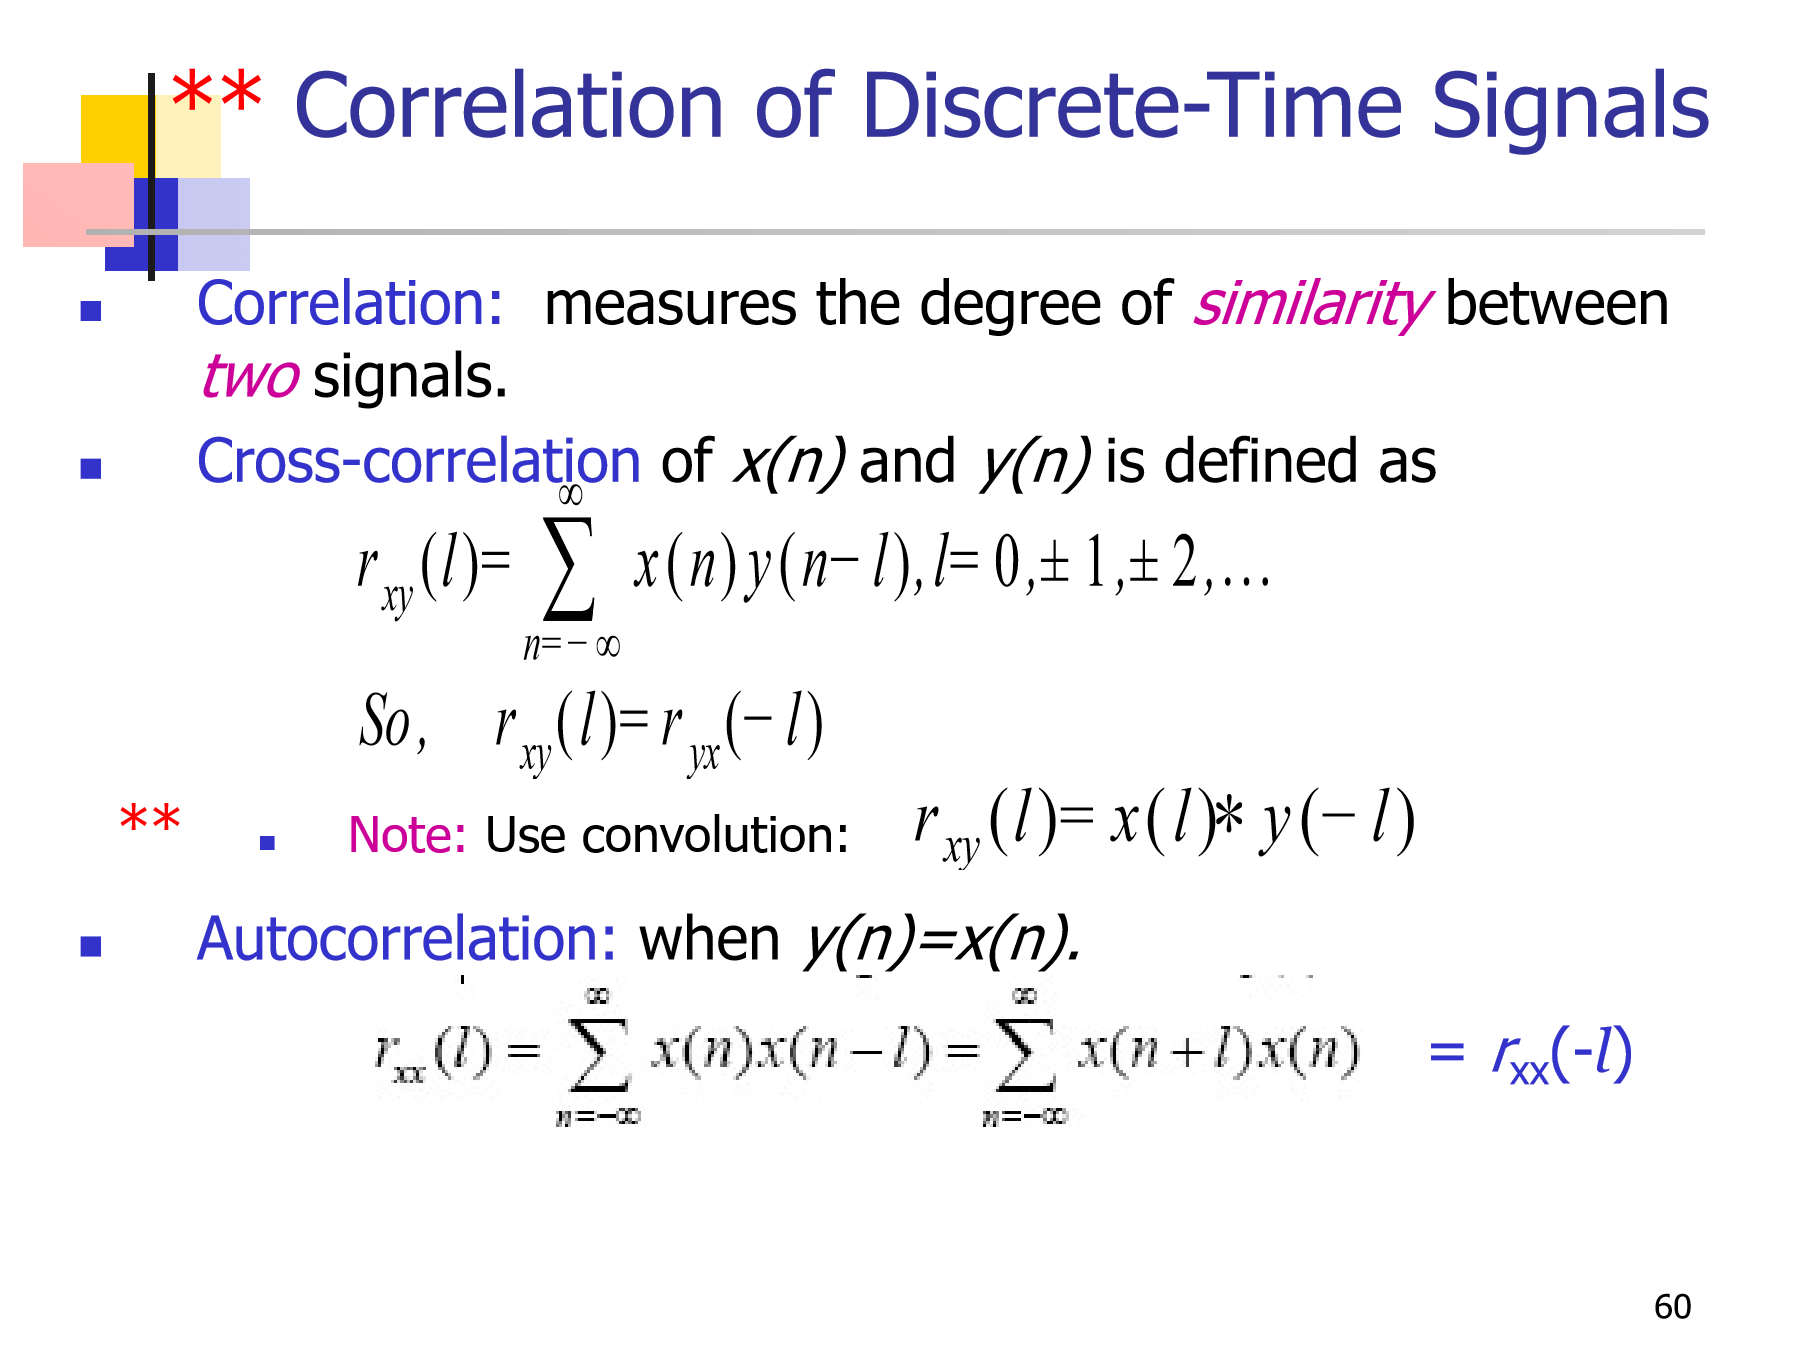

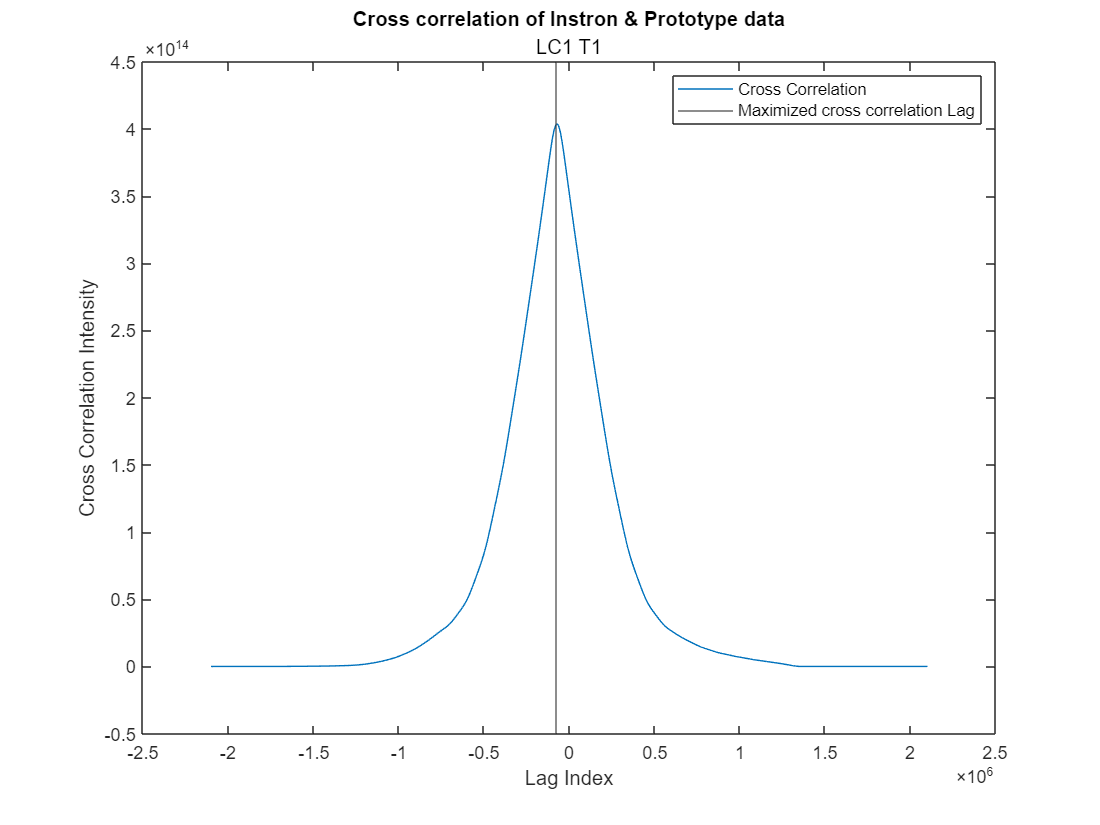

plot(lags2,new_cross_correl);
hold on
title("Cross correlation of Instron & Prototype data",{"LC"+load_cell_number + " T" + test_number});
xlabel("Lag Index");
ylabel("Cross Correlation Intensity");
xline(maxlags2);
legend("Cross Correlation", "Maximized cross correlation Lag")
set(gcf,'position',[10,10,900,600]);
hold off


%apply the shifting to the MCU
final_shifted_MCU_time = MCU_time_seconds + correspondingtimelag;

Using the lag which maximized cross correlation, we can translate this to a corresponding time lag, and shift the readings obtained using the prototype accordingly. The result is shown in the final graph below:

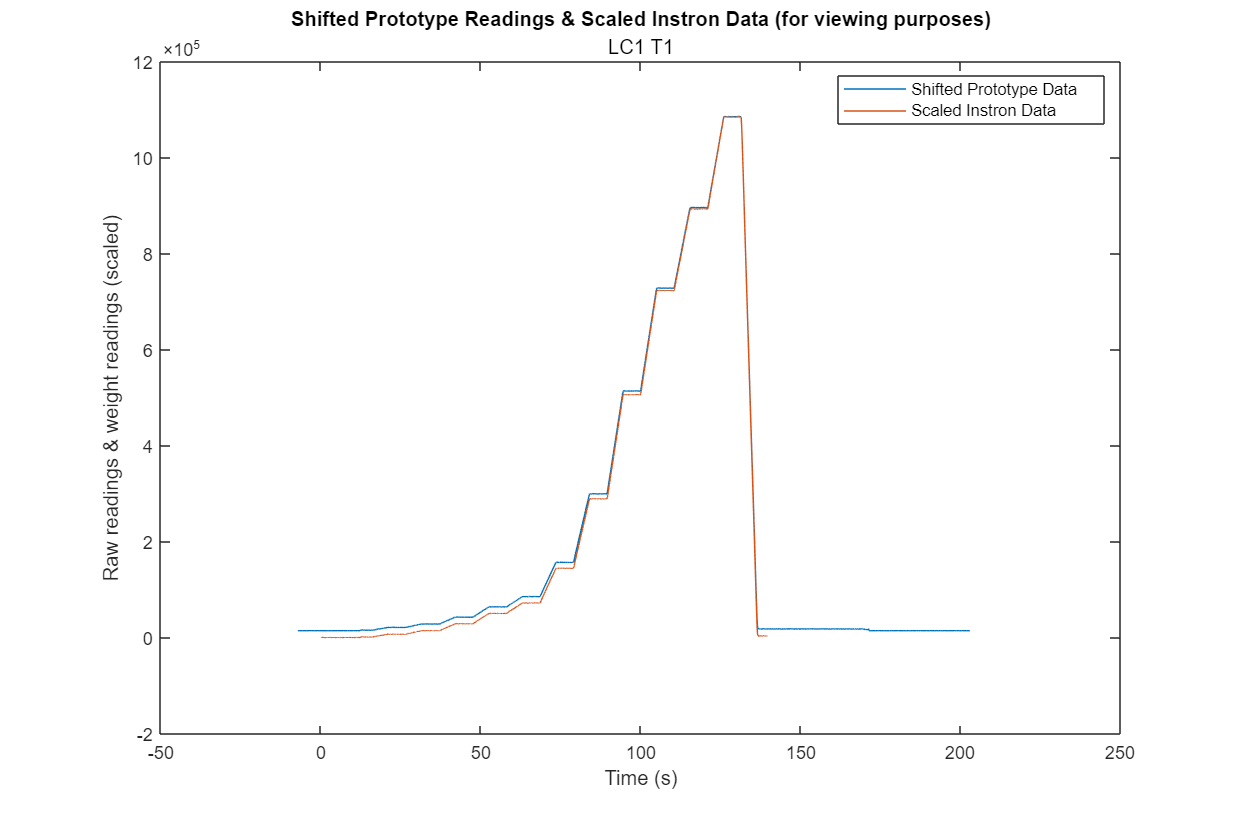

plot(final_shifted_MCU_time, MCU_load);
hold on
plot(Instron_time, Instron_load_scaled);
title("Shifted Prototype Readings & Scaled Instron Data (for viewing purposes)",{"LC"+load_cell_number + " T" + test_number});
xlabel("Time (s)"); %note that the time used for reference is the Instron timing;
ylabel("Raw readings & weight readings (scaled)");
legend("Shifted Prototype Data","Scaled Instron Data");
set(gcf,'position',[10,10,900,600]);
hold off